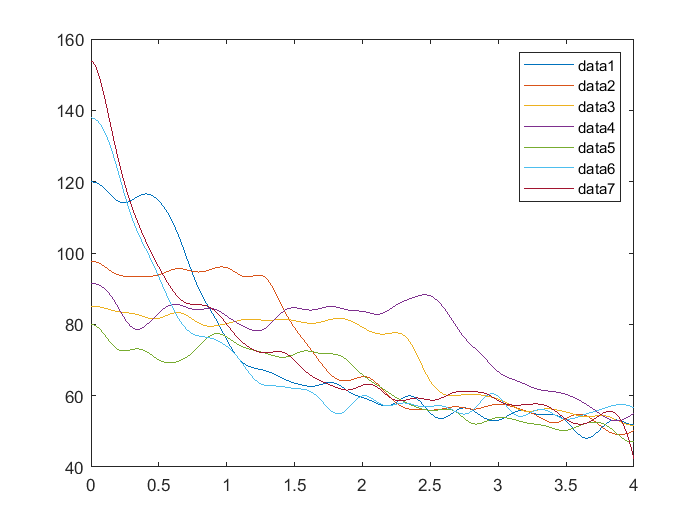

fs = P(1).fs;
tonicGCFR = [];
for i = 1:length(P)
    gcfr = P(i).avg_gcfr;
    [~,startPt] = max(gcfr);
    stopPt = startPt + 4*fs;
    tonicGCFR(i,:) = P(i).avg_gcfr(startPt : stopPt);
end
figure;
t = linspace(0,4,4*fs+1);
figure;
plot(t,tonicGCFR);
legend();

## Adaptation slope

descentFR = tonicGCFR(7,1:0.5*fs);
t1=linspace(0.0001,0.5,0.5*fs);
[xData, yData] = prepareCurveData( t1, descentFR );

% Set up fittype and options.
ft = fittype( 'power2' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.Robust = 'Bisquare';
% opts.StartPoint = [9397215.94371203 -3.68090399369325];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts )

fitresult =      General model Power2:
     fitresult(x) = a*x^b+c
     Coefficients (with 95% confidence bounds):
       a =      -124.8  (-125, -124.7)
       b =      0.4695  (0.467, 0.4719)
       c =         185  (184.7, 185.2)

gof = struct with fields:
           sse: 4.4501e+03
       rsquare: 0.9974
           dfe: 4997
    adjrsquare: 0.9974
          rmse: 0.9437


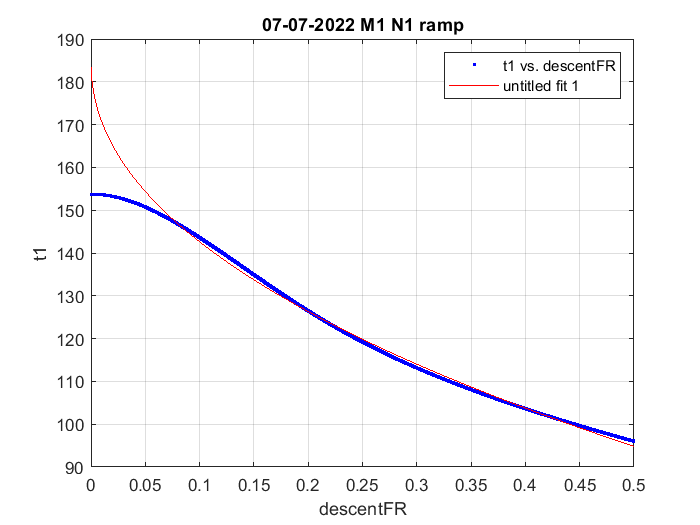


% Plot fit with data.
figure();
h = plot( fitresult, xData, yData );
legend( h, 't1 vs. descentFR', 'untitled fit 1', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'descentFR', 'Interpreter', 'none' );
ylabel( 't1', 'Interpreter', 'none' );
grid on

Stitle(join([string(date) replace(filename, '_',' ')], ' ' ));

T_ramp(irow,:) = table(date, filename, descentFR, b);
irow=irow+1;